## Steel Plate Defects

**Background:** [**Steel plate defects**](https://apmonitor.com/pds/uploads/Main/steel.txt) are extracted from photos of several faulty steel plates with surface imperfections. Image analysis revealed 27 different features to describe the steel fault. A total of 6 unique types of faults are categorized, with a final category of "other faults" for any type of fault that does not fit into the other specific 6 categories.

url = 'http://apmonitor.com/pds/uploads/Main/steel.txt';
data = readtable(url);
head(data);

    X_Minimum    X_Maximum    Y_Minimum     Y_Maximum     Pixels_Areas    X_Perimeter    Y_Perimeter    Sum_of_Luminosity    Minimum_of_Luminosity    Maximum_of_Luminosity    Length_of_Conveyer    TypeOfSteel_A300    TypeOfSteel_A400    Steel_Plate_Thickness    Edges_Index    Empty_Index    Square_Index    Outside_X_Index    Edges_X_Index    Edges_Y_Index    Outside_Global_Index    LogOfAreas    Log_X_Index    Log_Y_Index    Orientation_Index    Luminosity_Index    SigmoidOfAreas    Pastry    Z_Scratch

**Features:** There are 27 features that are used to predict the steel faults. These features are extracted from steel plate samples. Computer vision can automatically extract some of this information from images or manually extracted with a user inspecting each plate defect or photo of the steel plate.

- X_Minimum

- X_Maximum

- Y_Minimum

- Y_Maximum

- Pixels_Areas

- X_Perimeter

- Y_Perimeter

- Sum_of_Luminosity

- Minimum_of_Luminosity

- Maximum_of_Luminosity

- Length_of_Conveyer

- TypeOfSteel_A300

- TypeOfSteel_A400

- Steel_Plate_Thickness

- Edges_Index

- Empty_Index

- Square_Index

- Outside_X_Index

- Edges_X_Index

- Edges_Y_Index

- Outside_Global_Index

- LogOfAreas

- Log_X_Index

- Log_Y_Index

- Orientation_Index

- Luminosity_Index

- SigmoidOfAreas

**Labels:** There are 7 types of steel plate defects that are labelled with a 1 if present and 0 if not present with [**One-Hot Encoding**](https://apmonitor.com/pds/index.php/Main/FeatureEngineering). A unique aspect of this data set is that the labels are imbalanced, meaning that there is a large difference in the number of specific defects.

- Pastry

- Z_Scratch

- K_Scatch

- Stains

- Dirtiness

- Bumps

- Other_Faults

In cases where there is a large imbalance, a strategy is to [**synthetically generate new data sets to improve the balance**](https://machinelearningmastery.com/multi-class-imbalanced-classification/). That strategy is not taken in this case study but could be an option to improve the classification training. The fault label is not stored as a sequential value (e.g. fault label as 0-6) but is [**One-hot encoded**](https://en.wikipedia.org/wiki/One-hot) to translate the fault label into a binary representation (0 or 1) for each fault. There are 7 additional columns of data with 1 if the fault exists and 0 if the fault does not exist.

## Detect Outliers

Detect outliers and remove bad data if present.

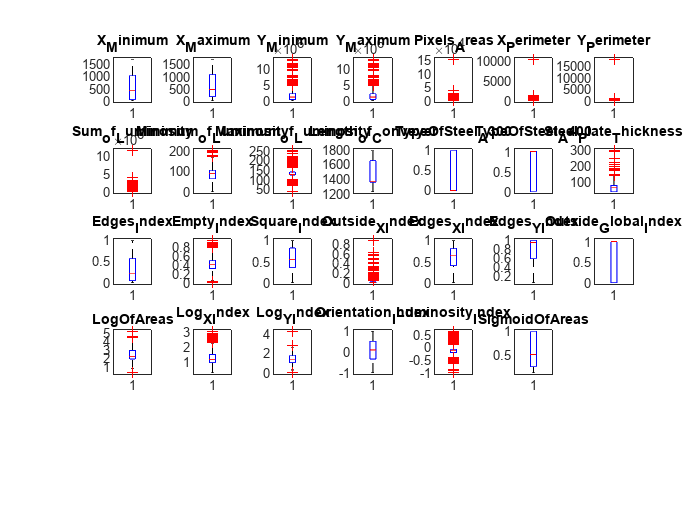

features = data(:,1:27).Properties.VariableNames;
for i = 1:numel(features)
    subplot(5, 7, i);
    boxplot(data.(features{i}));
    title(features{i});
end

figure('visible','off')

**Data Exploration:** Generate summary statistics with a profiling report to [**statistically characterize the data**](https://apmonitor.com/pds/index.php/Main/StatisticsMath). Use box plots to identify any outliers in the data. Remove any outliers from the data set. Generate a pair plot and correlation matrix. What factors are highly correlated to the steel faults? Generate a bar chart that shows the imbalance of faults in the data.

features = data(:,1:27).Properties.VariableNames;
labels = data(:,28:end).Properties.VariableNames

labels = 1×7 cell array
    {'Pastry'}    {'Z_Scratch'}    {'K_Scatch'}    {'Stains'}    {'Dirtiness'}    {'Bumps'}    {'Other_Faults'}


X = data(:,1:27);
y = data(:,28:end);

% counts = groupsummary(y,"Pastry")
% counts = groupcounts(table2array(y))
counts = varfun(@groupcounts,y,"InputVariables",labels);
counts = counts(2,:)

counts = 1×7 table
    groupcounts_Pastry    groupcounts_Z_Scratch    groupcounts_K_Scatch    groupcounts_Stains    groupcounts_Dirtiness    groupcounts_Bumps    groupcounts_Other_Faults
    __________________    _____________________    ____________________    __________________    _____________________    _________________    ________________________

           158                     190                     391                     72                     55                     402                     673           


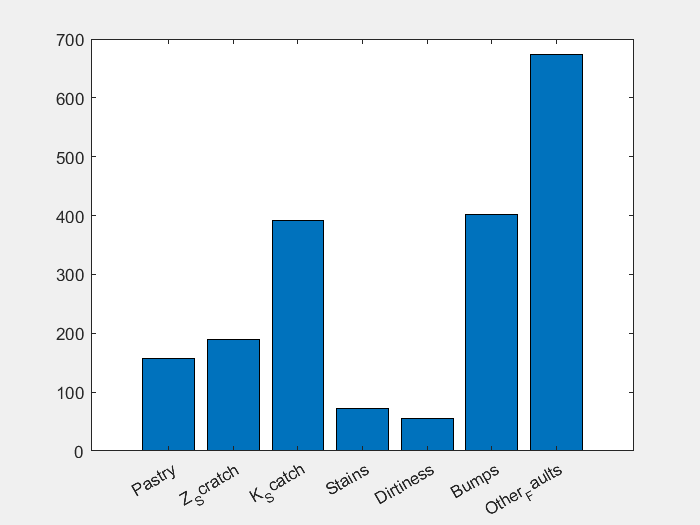

figure('visible','off')
figure('visible','on')
bar(table2array(counts))
set(gca,'XTick',1:length(labels),'XTickLabel',labels)

**Classification of Faults:** Train and test a classifier to distinguish between steel plate faults.

Randomly select values that split the data into a train (80%) and test (20%) set.

features = data.Properties.VariableNames(1:end-7);
labels = data.Properties.VariableNames(end-6:end);

rng("default") % For reproducibility of the data partition
c = cvpartition(height(data),"Holdout",0.20);
trainingIdx = training(c); % Training set indices
X_train = X(trainingIdx,:);
y_train = y(trainingIdx,:);
testIdx = test(c); % Indices for the test set
X_test = X(testIdx,:);
y_test = y(testIdx,:);
X_train_ar = table2array(X_train);

### Select Best Features

Select the best features for the classification.

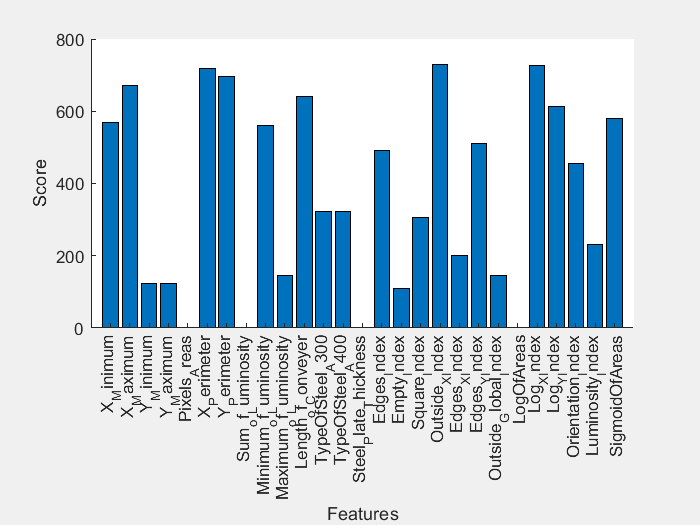

X_s = table2array(data(:,features));
y_s = table2array(data(:,labels));
y_scat = onehotdecode(y_s, labels, 2);

[fit, scores] = fscchi2(X_s, y_scat);
Specs = features';
figure('visible','off')
figure('visible','on')

% Visualize feature scores
bar(scores)
set(gca, 'XTick', 1:length(features), 'XTickLabel', features)
xlim([0 length(features)+1])
xlabel('Features')
ylabel('Score')
box off

Determine any evidence of overfitting by plotting the training and test (validation) loss functions by epoch.

y_cat = onehotdecode(table2array(y_train), labels, 2);
X_train_ar = table2array(X_train)

X_train_ar = 1.0e+07 *

    0.0000    0.0000    0.0271    0.0271    0.0000    0.0000    0.0000    0.0024    0.0000    0.0000    0.0002    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0001    0.2538    0.2538    0.0000    0.0000    0.0000    0.0011    0.0000    0.0000    0.0002    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0001    0.0369    0.0369    0.0000    0.0000    0.0000    0.0019    0.0000    0.0000    0.0001         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0100    0.0100    0.0001    0.0000    0.0000    0.0062    0.0000    0.0000    0.0001         0    0.0000    0.0000    0.0000    0.0000   

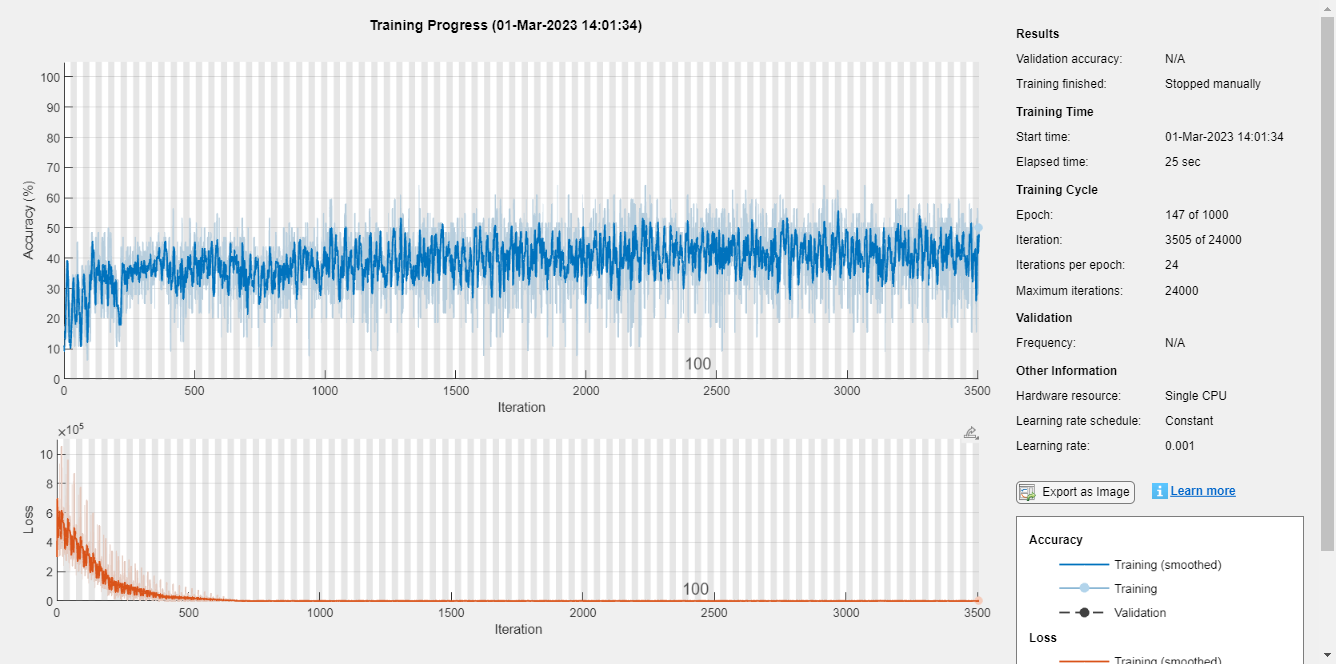


layers = [ ...
    featureInputLayer(width(X_train))
    reluLayer
    fullyConnectedLayer(7)
    softmaxLayer
    classificationLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',1000,...
    'InitialLearnRate',0.001, ...
    'SquaredGradientDecayFactor',0.99,...
    'MiniBatchSize',64,...
    'Verbose',false, ...
    'Plots','training-progress');

[net,info] = trainNetwork(X_train_ar,y_cat,layers,options);

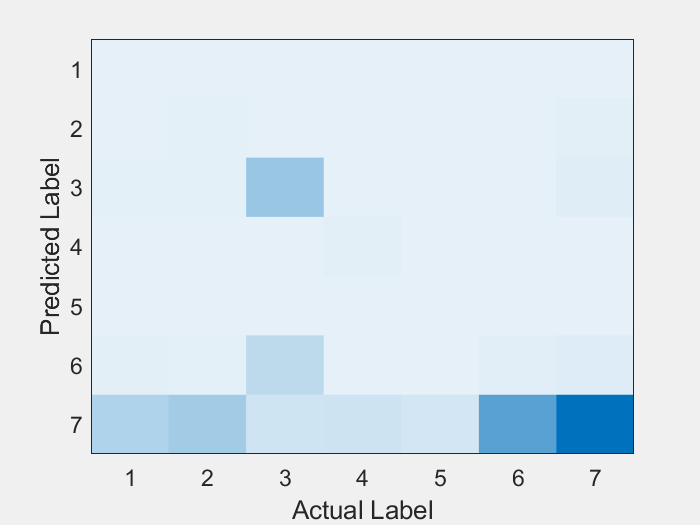

figure('visible','off')
figure('visible','on')

% Make predictions and save in table
yp = predict(net, X_train);
yp = array2table(yp, 'VariableNames', y_test.Properties.VariableNames);

% Extract predicted labels and probabilities
[~,predicted_label] = max(yp{:,:},[],2);
predicted_prob = max(yp{:,:},[],2);
[~,actual_label] = max(y_train{:,:},[],2);

% Display probabilities, with the most likely label highlighted and the actual label displayed
yp_ActualFault = categorical(actual_label);

% Plot the confusion matrix
cm = confusionmat(predicted_label, actual_label);
heatmap(cm, 'ColorbarVisible', 'off', 'GridVisible', 'off', 'FontSize', 14, 'XLabel', 'Actual Label', 'YLabel', 'Predicted Label', 'CellLabelColor', 'none');

% textStrings = num2str(cm(:),'%d');
% textStrings = strtrim(cellstr(textStrings));
% [x,y] = meshgrid(1:size(cm,1),1:size(cm,2));
% hStrings = text(X(,:),y(,:),textStrings(,:), 'HorizontalAlignment','center');
% midValue = mean(get(gca,'CLim'));
% textColors = repmat(cm(:) > midValue,1,3);
% set(hStrings, {'Color'}, num2cell(textColors,2));

% function fit_transform = fit_tranform(data)
%     tmp_mean = 0;
%     tmp_std = 0;
%     res = data;
%     for i = 1:width(data)
%         cc = data(:,i);
%         tmp_mean = mean(cc);
%         temp_std = (cc-min(cc))/(max(cc)-min(cc));
%         res(:,i) = temp_std*(1-0)+0;
%     end
%     fit_transform = res;
% end
